# ECG grand average

Stimulus-locked grand average. For each trial, a baseline was created by averaging physiological time-series data from 3 seconds before the thermal stimulation onset.  A stimulus-locked physiological response was generated by subtracting the baseline value from the data in the 20-second period after the stimulation onset. 

clear;
close all;

basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';
cd(basedir);

load('../data/CRB_dataset_ECG_lpf1Hz_DS25Hz_021916.mat');
% load('../data/CRB_dataset_ECG_lpf5Hz_DS25Hz_120516.mat');

figdir = '../figures';

for j = [1:38 40:numel(D.Continuous.data)] % 39th subj: missing data 
    
    scr = D.Continuous.data{j};
    
    ons = D.Event_Level.data{j}(:,5);
    
    for ii = 1:6
        for jj = 1:3
            signal{j}.cond{ii, jj} = [];
        end
    end
        
    for i = 1:numel(ons)
        
        temp_lev = D.Event_Level.data{j}(i,11)-43;
        reg_lev = D.Event_Level.data{j}(i,16)+2;
        a = round((ons(i)-3)*25);
        signal{j}.cond{temp_lev, reg_lev}(end+1,:) = scr(a:(a+(23*25))); 
    end
    
end


clear signal_m;
for i = 1:6
    for j = 1:3
        kk = 0;
        for subj = [1:38 40:numel(signal)]
            kk = kk + 1;
            signal_m{i,j}(kk,:) = mean(signal{subj}.cond{i,j} - repmat(mean(signal{subj}.cond{i,j}(:,1:75),2), 1, size(signal{subj}.cond{i,j},2)));
                                                     % subtracting the baseline, and then average
        end
    end
end


## All temperature; ECG

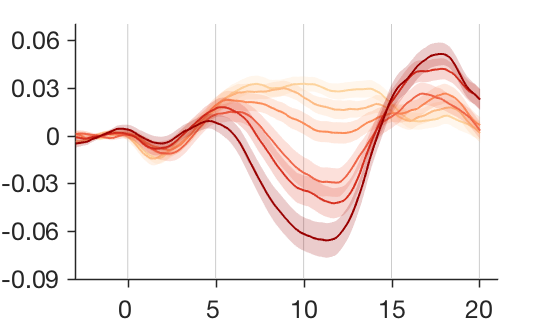

close all;

x = 1:576;
create_figure('shading');
cols = [0.9922    0.8314    0.6196
    0.9922    0.7333    0.5176
    0.9882    0.5529    0.3490
    0.9373    0.3961    0.2824
    0.8431    0.1882    0.1216
    0.6000         0         0];

for i = (3:5:24)*25
    line([i i], [-.09 .07], 'col', [.8 .8 .8], 'linewidth', 1);
end

for i = 1:6
    hold on;
    wani_plot_shading(x, mean(cat(1,signal_m{i,:})), ste(cat(1,signal_m{i,:})), 'color', cols(i,:), 'alpha', .2);
    % wani_plot_shading(x, mean(cat(1,signal_m{i,:})), repmat(wsbar(cat(1,signal_m{i,:})), 1, size(cat(1,signal_m{i,:}),2)), 'color', cols(i,:), 'alpha', .2);
    % plot(x, mean(cat(1,signal_m{i,:})), 'color', cols(i,:), 'linewidth', 2);
end

set(gcf, 'position', [50   126   549   324]);
set(gca, 'ylim',  [-.09 .07], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (3:5:24)*25, 'ytick', -.09:.03:.1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
set(gca, 'fontSize', 25);


savename = fullfile(figdir, 'Temp_all_ECG_grandavg_full.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename)
